For illustration, here is a spline interpolant using just a few nodes. 

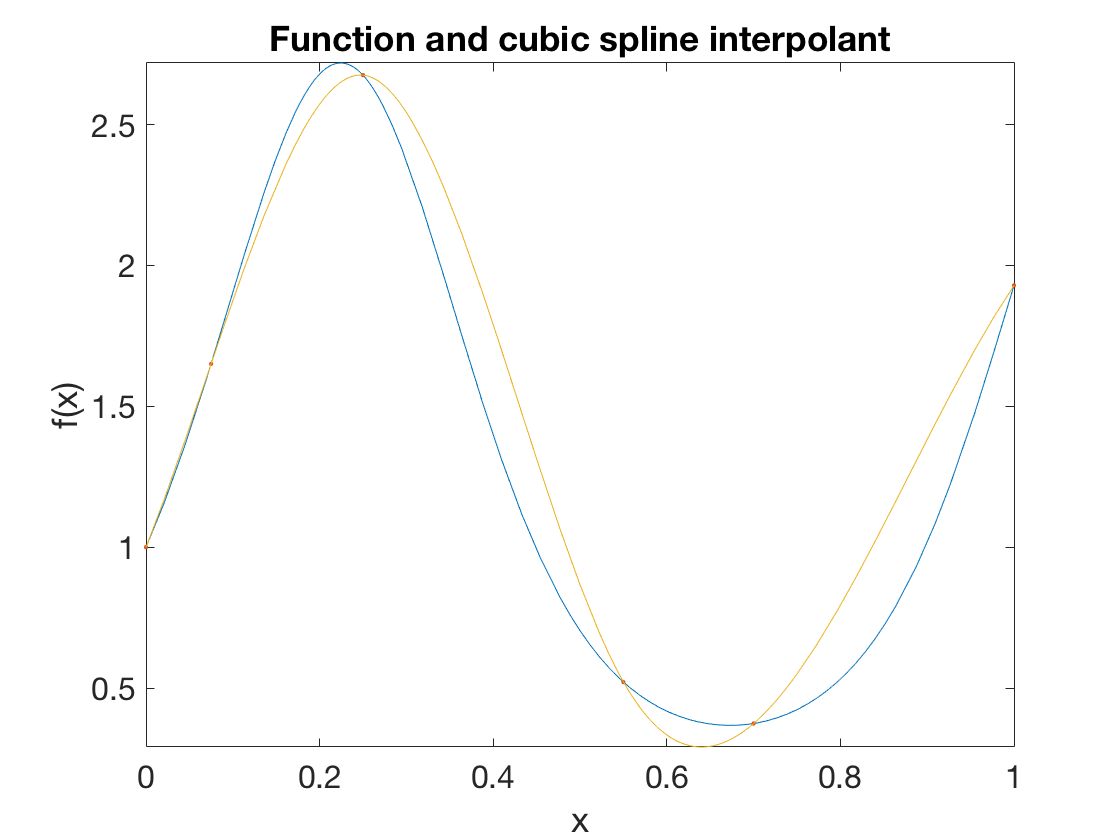

f = @(x) exp(sin(7*x));         
fplot(f,[0,1])
t = [0, 0.075, 0.25, 0.55, 0.7, 1]';  % nodes
y = f(t);                            % values at nodes
hold on, plot(t,y,'.')
S = spinterp(t,y);
fplot(S,[0,1])
xlabel('x'), ylabel('f(x)')   % ignore this line
title('Function and cubic spline interpolant')   % ignore this line

Now we look at the convergence rate as the number of nodes increases.

x = linspace(0,1,10001)';  % sample the difference at many points
n_ = 2.^(3:0.5:8)';
err_ = 0*n_;

for i = 1:length(n_)
    n = n_(i);
    t = linspace(0,1,n+1)';   % interpolation nodes
    S = spinterp(t,f(t));
    err = norm( f(x) - S(x), inf );
    err_(i) = err;
end

Since we expect convergence that is $O(h^4)=O(n^{-4})$, we use a log-log graph of error and expect a straight line of slope $-4$.

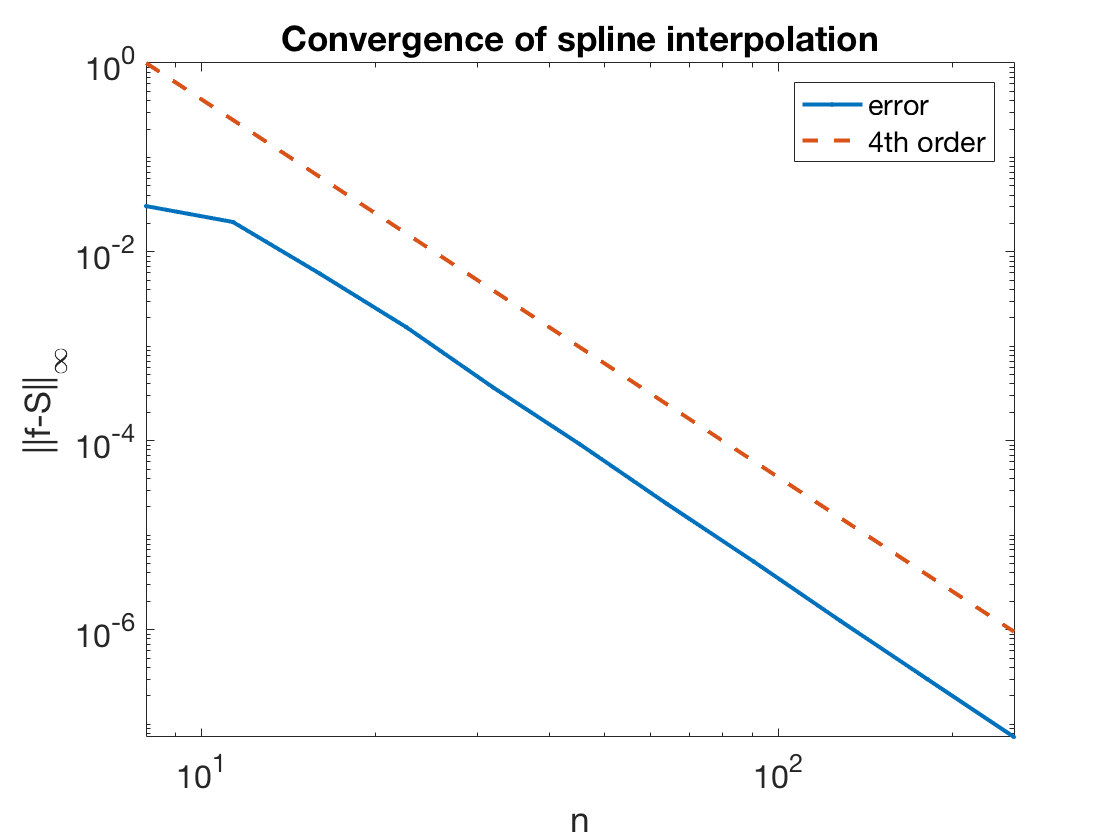

clf, loglog( n_, err_, '.-' )
hold on, loglog( n_, (n_/n_(1)).^(-4), '--' )
xlabel('n'), ylabel('||f-S||_\infty'), axis tight   % ignore this line
title('Convergence of spline interpolation')   % ignore this line
legend('error','4th order')   % ignore this line